# verifying self-shadowing function

clc
clear
close all

const = orbitConst

const = フィールドをもつ struct :
       GE: 3.9860e+05
      GEm: 3.9860e+14
    GEday: 2.9755e+15
       J2: 0.0011
       RE: 6.3781e+03
      REm: 6378137
       WE: 7.2921e-05
       fE: 0.0034
     EPS0: 0.4091
    GSday: 9.9069e+20
       GS: 1.3271e+11
       RS: 696000
      RSm: 696000000
       AU: 1.4960e+08
      AUm: 1.4960e+11
       S0: 1357
       GM: 4.9028e+03
      GMm: 4.9028e+12
    GMday: 3.6599e+13
    J2000: 2451545
        c: 299792458


## load object

sat = readSC('boxWing4.obj');

number of vertices:
   242

number of faces:
   236



sat.kappa = 0;
sat.Cd = 0.5;
sat.Cs = 0.5;
sat.Ca = 0.5;

size(sat.vertices) % nVertices

ans =    242     3


size(sat.faces) % nFaces

ans =    236     4


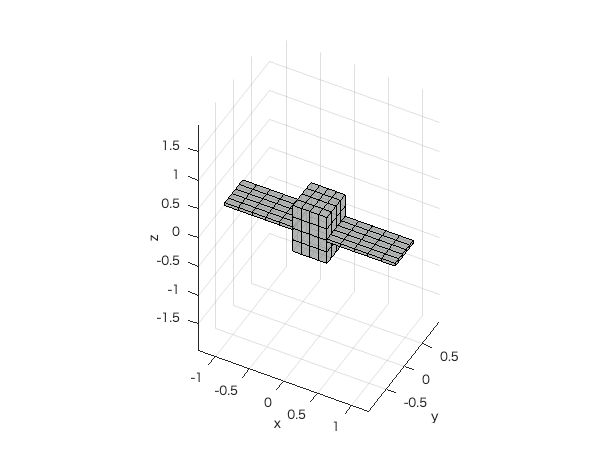


showSC(sat)

## parameters

sun = [0.8 -0.3 0.62]; % nominal sun vector
sun = rand(1,3);
sun = sun./norm(sun);
sunDist = const.AU * 10^3; % m

### codegen

mex化する関数に `%#codegen` をつける

つけたあとに出てくるエラーを解消する

`codegen (filename).(拡張子) -args {}`

**-argsの中身の型はmex化関数を呼び出すときの引数の型と同じにする**

`(filename)_mex.mexmaca64`ファイルと`codegen`フォルダが作成される

使い方は普通の関数と同じ

`(filename)_mex(引数)`

% tmpsunB = ones(1,3);
% tmpd = ones(1,1);
% codegen -report srpSimple.mlx -args {sat,tmpsunB,tmpd,const}
tmpsun = ones(1,3,1);
sat.shadowFlag = zeros(size(sat.faces,1),1);
tmpN = [0 0 1];
tmpVertJ = ones(3,3);
tmpPos = [1, 1, 1];
% codegen -report calcSelfShadow.mlx -args {tmpsun, tmpN, tmpVertJ, tmpPos}

% codegen -report selfShadow.mlx -args {sat, tmpsun} % 三角facetと四角facetに応じて作り直さないとダメ


% sat = srpSimple(sat, sun, sunDist, const); % calc. SRP

tic
sat = selfShadow(sat, sun); % calc self shadowing
toc

経過時間は 0.074724 秒です。



tic
satMex = selfShadow_mex4(sat, sun); % calc self shadowing
toc

経過時間は 0.000915 秒です。


## show figures

for non-mex function

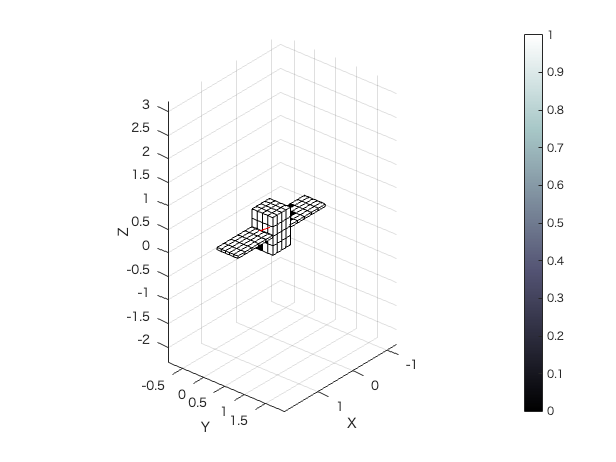

figure
hold on
cb = colorbar;
colormap bone
% caxis([0 1e-7])

satFig = patch('Faces',sat.faces,'Vertices',sat.vertices);
set(satFig, 'FaceColor', 'b');
set(satFig, 'FaceLighting','phong','EdgeLighting','phong');
set(satFig, 'FaceVertexCData', sat.shadowFlag, 'FaceColor', 'flat')

axis equal
grid on
xlabel('X'),ylabel('Y'),zlabel('Z')
view(130,30);
quiver3(0, 0, 0, 3*sun(1),3*sun(2),3*sun(3) ,'r') % show sun direction

for mex function

figure
hold on
cb = colorbar;
colormap bone
% caxis([0 1e-7])

satFig = patch('Faces',satMex.faces,'Vertices',satMex.vertices);
set(satFig, 'FaceColor', 'b');
set(satFig, 'FaceLighting','phong','EdgeLighting','phong');
set(satFig, 'FaceVertexCData', satMex.shadowFlag, 'FaceColor', 'flat')

axis equal
grid on
xlabel('X'),ylabel('Y'),zlabel('Z')
view(130,30);
quiver3(0, 0, 0, 3*sun(1),3*sun(2),3*sun(3) ,'r') % show sun direction

## calculation for variable attitude

% atti = 0:10:80; % attitude angle , deg
% for i = 1:length(atti) DCM = ZYX2DCM(deg2rad(atti(i)), 0.0, 0.0)'; % NOTE: vector rotation sun_var = DCM * sun;
%     sat = SRP_LPS_obj(sat, sun_var, sun_dist); % SRP calculation
%     sat = calcShadow_obj(sat, sun_var); % shadow flag calculation
%     quiver3(0, 0, 0, 3*sun_var(1),3*sun_var(2),3*sun_var(3) ,'r')
%     set(satFig, 'FaceVertexCData', sat.shadowFlag);
%     pause(0.5)
%     % movFrame(i) = getframe;
% end

% movie(movFrame);